# Projekt 2

#### **Przykład 1**

Przesunięcie lewego górnego rogu obrazu w punkt wskazany myszką przez użytkownika z zawinięciem elementów.

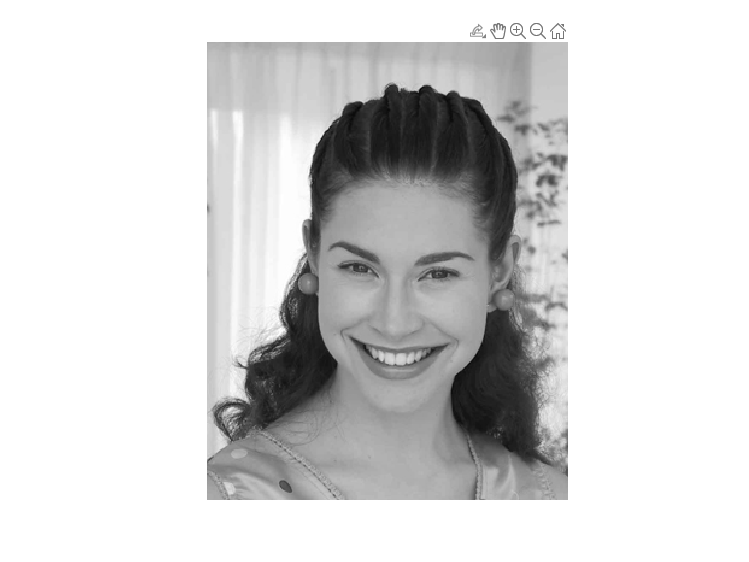

x = 60.0633

y = 80.5655

L1 = imread('portret.jpg');
figure; 
imshow(L1);
[x,y] = ginput(1)

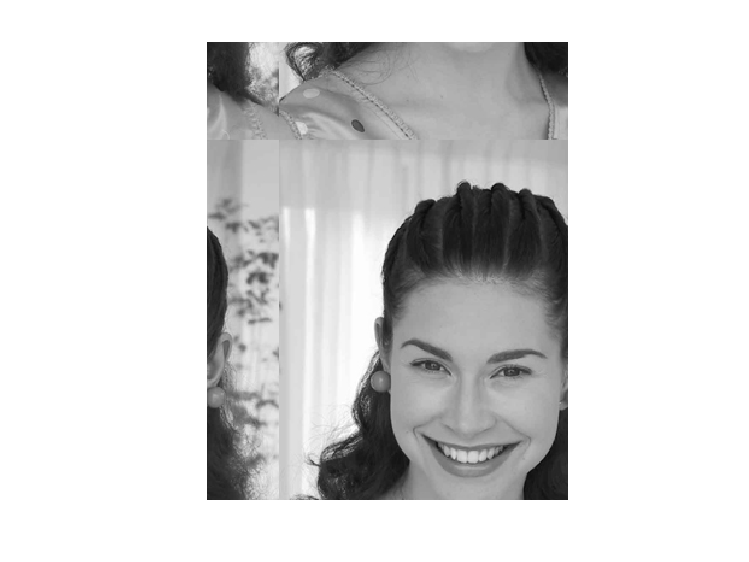

L2 = circshift (L1, [round(y) round(x)]);
imshow(L2);

*[x,y,button] = ginput(1)  **- pobranie współrzędnych x, y punktu, wskazywanego przez kursor; do zmiennej button zwracane jest, który przycisk myszy został naciśnięty, 1 - lewy, 2 - środkowy, 3 - prawy; argumentem jest liczba pobrań*

*circshift (L, [a b]) – przesuwa macierz o *a* elementów w dół i *b* w prawo. Wszystkie elementy są odpowiednio zawijane.*

### Zadanie 1

Napisz program, który pozwoli na przesunięcie obrazu o zadany wektor (z zawinięciem elementów obrazu). Użytkownik wskazuje najpierw punkt początkowy, a następnie punkt końcowy wektora. Program powtarza operację na przetworzonym obrazie, dopóki nie zostanie naciśnięty prawy przycisk myszy.

x_1 = 82.4651

y_1 = 202.5306

button = 1

x_2 = 249.2336

y_2 = 218.2948

button = 1

F1 = 380×300 uint8 matrix
   181   180   180   178   178   177   176   176   177   180   180   180   180   180   180   180   180   180   180   180   179   177   176   177   177   176   176   177   177   177   177   176   175   174   174   174   174   174   174   175   175   175   176   174   175   175   175   175   174   174
   181   181   181   179   179   179   177   178   178   180   180   180   180   180   180   180   180   180   180   181   177   177   177   177   177   174   173   176   179   180   180   180   176   173   174   174   173   174   174   175   176   176   176   175   175   175   175   175   174   174
   181   181   181   183   183   183   180   180   180   180   180   180   181   180   180   180   180   180   180   180   177   177   177   177   177   174   173   176   179   180   180   179   176   172   173   174   174   174   174   176   177   176   176   175   175   175   175   175   174   173
   182   182   182   183   183   184   182   183   181   179   179   18

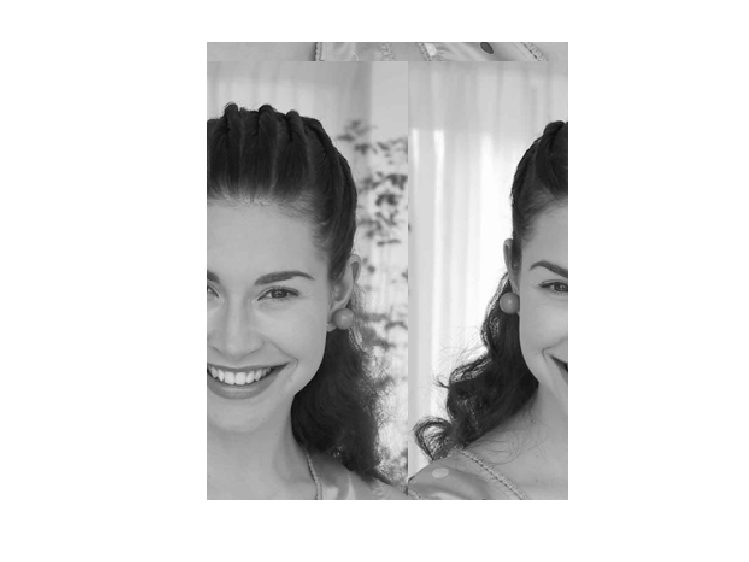

x_1 = 163.7751

y_1 = 209.9978

button = 3

F1 = imread('portret.jpg');

while 1
    imshow(F1);
    [x_1,y_1,button] = ginput(1)
    if button == 3
        break;
    end

    [x_2, y_2,button] = ginput(1)
    if button == 3
        break;
    end
    x = x_2 - x_1;
    y = y_2 - y_1;


    F1 = circshift(F1, [round(y) round(x)])
end

### Zadanie 2

Napisz program, który pozwoli użytkownikowi na zaznaczenie fragmentu obrazka (użytkownik wskazuje lewy górny i prawy dolny róg prostokąta) i wyświetlenie w nowym oknie tego fragmentu powiększonego 10-krotnie. Wyświetl wyniki dla trzech różnych metod interpolacji opisując odpowiednio okna.

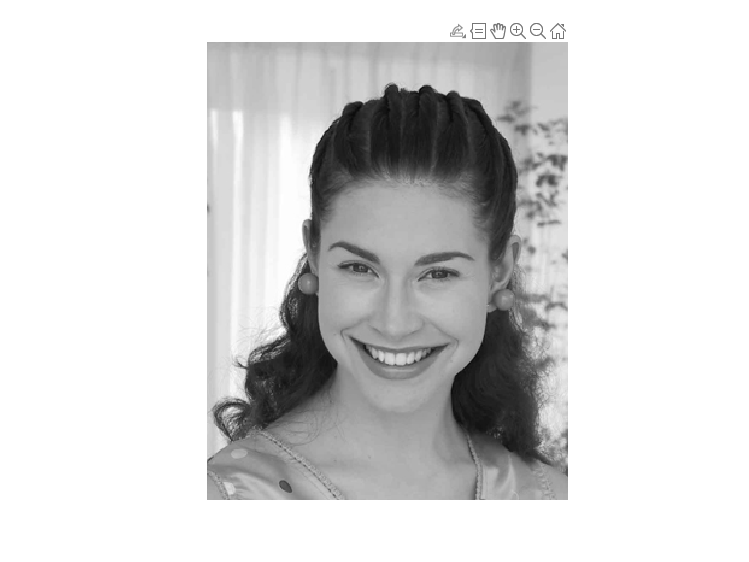

x =    97.3996
  225.1725


y =   159.3865
  208.3384


org = imread('portret.jpg');
figure
set(gcf,'Visible','on') %wymuszenie wydzielenia okna
imshow(org);
[x, y] = ginput(2)

part = org(y(1,1):y(2,1), x(1,1):x(2,1))

part = 49×128 uint8 matrix
   144   145   147   150   153   153   152   155   157   157   157   157   160   160   160   162   162   163   165   165   165   165   165   165   165   165   167   167   167   172   172   173   175   175   175   175   175   176   178   182   180   180   180   182   182   182   182   182   181   180
   147   146   150   153   153   153   154   155   157   157   157   157   160   161   160   162   162   163   165   165   165   165   165   165   165   165   167   167   167   172   172   173   175   175   175   175   175   175   179   181   180   180   180   182   182   182   182   181   182   180
   147   147   151   152   152   153   151   151   155   157   158   156   160   160   160   162   162   164   165   165   166   167   167   167   166   167   170   170   170   171   170   171   175   175   174   176   179   180   180   180   180   180   180   180   179   181   182   182   181   179
   148   148   151   152   152   153   151   151   155   157   157   1

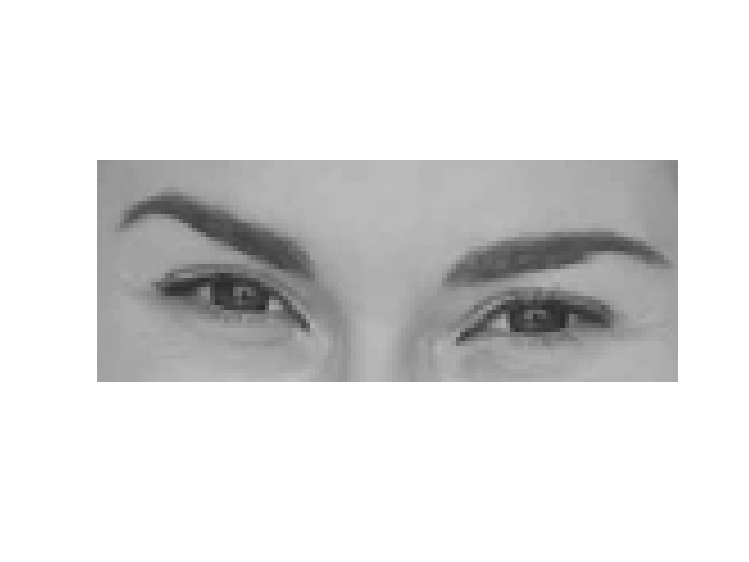

figure
set(gcf,'Visible','on') %wymuszenie wydzielenia okna
imshow(part);

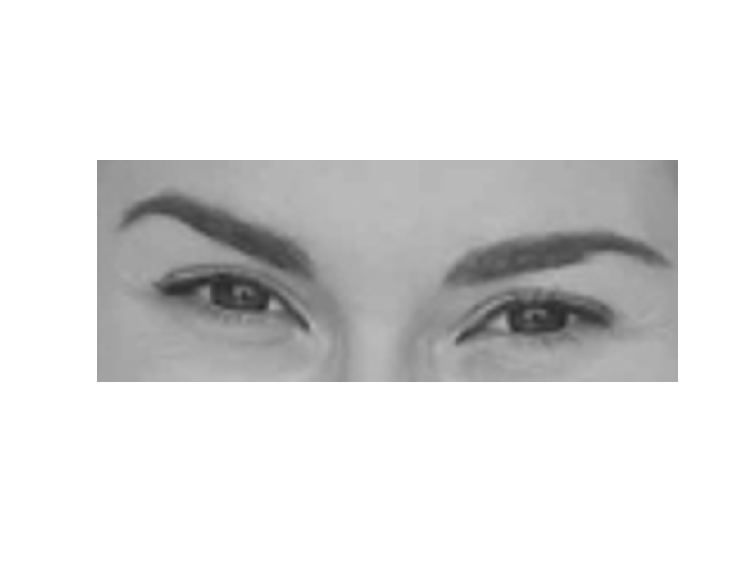

resized = imresize(part, 10);
figure
set(gcf,'Visible','on') %wymuszenie wydzielenia okna
imshow(resized);

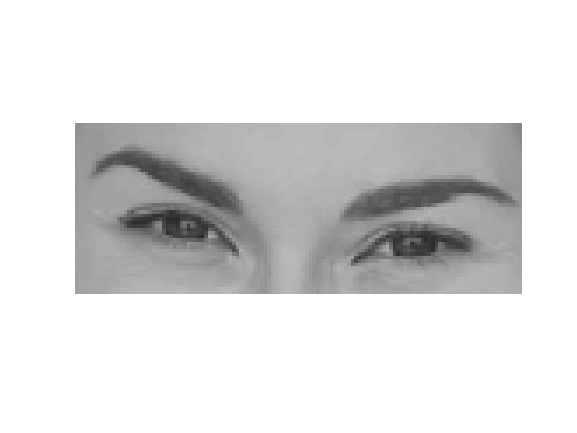


resized_nearest=imresize(part, 10, "nearest");
figure (Name='nearest')
set(gcf,'Visible','on') %wymuszenie wydzielenia okna
imshow(resized_nearest);

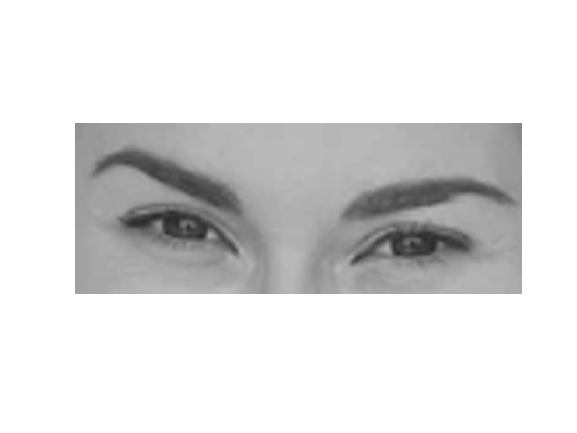

resized_bicubic=imresize(part, 10, "bicubic");
figure (Name='bicubic')
set(gcf,'Visible','on') %wymuszenie wydzielenia okna
imshow(resized_bicubic);

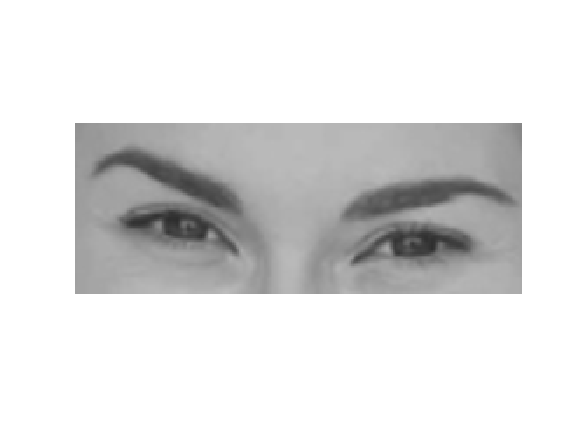

resized_trangle=imresize(part, 10,"triangle");
figure(Name='triangle')
set(gcf,'Visible','on') %wymuszenie wydzielenia okna
imshow(resized_trangle);

Przydatne funkcje: **imresize**

#### **Przykład 2**

Użycie prostego menu do sterowania jasnością obrazu

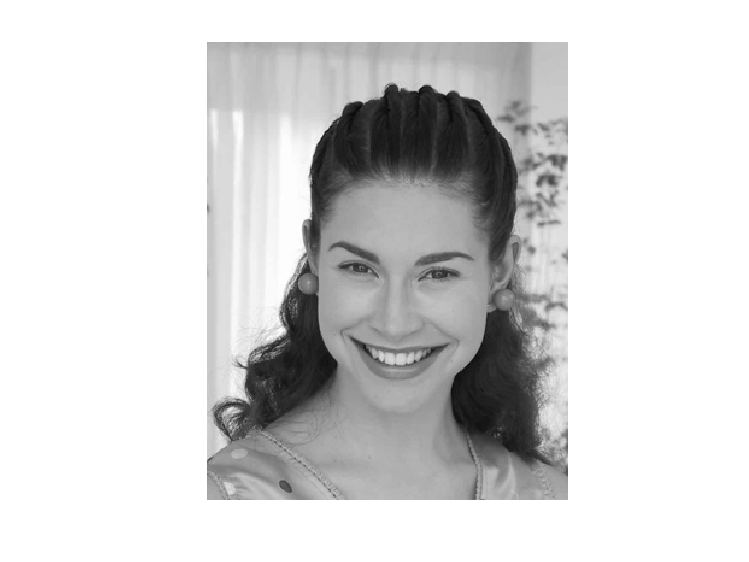

L1 = imread('portret.jpg');
figure
set(gcf,'Visible','on') %wymuszenie wydzielenia okna
imshow(L1); 
while 0<1
    wyb = menu('Menu','Dodaj 10','Odejmij 10','Wyjdz');
    switch wyb
        case 1
            L1 = L1 + 10;
            imshow(L1);
        case 2
            L1 = L1 - 10;
            imshow(L1);
        case 3
            close
            break
    end
end

*menu(tytuł, opcja1, opcja2,…) – tworzenie oknie menu o tytule *tytuł* i przyciskami podpisanymi jak *opcje*. Zwraca liczbę, odpowiadającą numerowi przycisku, który został naciśnięty.*

### Zadanie 3

Stwórz i oprogramuj menu, w którym użytkownik będzie mógł wybrać następujące operacje na obrazie:

- dodanie losowej wartości z przedziału 0.0 – 1.0

- odjęcie losowej wartości z przedziału 0.0 – 1.0

- logarytmowanie

- pierwiastkowanie

- potęgowanie

- przywrócenie oryginalnego obrazu

Pamiętaj  o zastosowaniu operatorów tablicowych tam, gdzie jest to konieczne.

L0 = imread('portret.jpg');
L0 = double(L0)/255

L0 =     0.6706    0.6824    0.6863    0.6863    0.6863    0.6863    0.6863    0.6941    0.7020    0.6941    0.6863    0.6824    0.6902    0.6824    0.6745    0.6627    0.6588    0.6588    0.6627    0.6784    0.6902    0.6980    0.6980    0.6980    0.6863    0.6863    0.6902    0.6902    0.6902    0.6863    0.6745    0.6667    0.6431    0.6314    0.6471    0.6588    0.6706    0.6784    0.6784    0.6706    0.6588    0.6706    0.6706    0.6706    0.6706    0.6706    0.6745    0.6784    0.6784    0.6784
    0.6784    0.6941    0.6980    0.6980    0.6980    0.6980    0.6980    0.6980    0.6980    0.6980    0.6980    0.6980    0.7020    0.6980    0.6863    0.6706    0.6706    0.6706    0.6745    0.6863    0.6980    0.7059    0.7098    0.7098    0.6980    0.7020    0.6941    0.6863    0.6902    0.6863    0.6706    0.6667    0.6471    0.6431    0.6588    0.6706    0.6784    0.6863    0.6863    0.6784    0.6706    0.6706    0.6706    0.6706    0.6706    0.6706    0.6745    0.6784    0.6784    

L1 = L0

L1 =     0.6706    0.6824    0.6863    0.6863    0.6863    0.6863    0.6863    0.6941    0.7020    0.6941    0.6863    0.6824    0.6902    0.6824    0.6745    0.6627    0.6588    0.6588    0.6627    0.6784    0.6902    0.6980    0.6980    0.6980    0.6863    0.6863    0.6902    0.6902    0.6902    0.6863    0.6745    0.6667    0.6431    0.6314    0.6471    0.6588    0.6706    0.6784    0.6784    0.6706    0.6588    0.6706    0.6706    0.6706    0.6706    0.6706    0.6745    0.6784    0.6784    0.6784
    0.6784    0.6941    0.6980    0.6980    0.6980    0.6980    0.6980    0.6980    0.6980    0.6980    0.6980    0.6980    0.7020    0.6980    0.6863    0.6706    0.6706    0.6706    0.6745    0.6863    0.6980    0.7059    0.7098    0.7098    0.6980    0.7020    0.6941    0.6863    0.6902    0.6863    0.6706    0.6667    0.6471    0.6431    0.6588    0.6706    0.6784    0.6863    0.6863    0.6784    0.6706    0.6706    0.6706    0.6706    0.6706    0.6706    0.6745    0.6784    0.6784    


figure
set(gcf,'Visible','on') %wymuszenie wydzielenia okna
imshow(L1); 

while 1
    wyb = menu('Menu','Dodaj random','Odejmij random','logarytmowanie','pierwiastkowanie','potęgowanie','przywrócenie oryginalnego obrazu','Wyjdz');
    switch wyb
        case 1
            L1 = L1 + rand();
            imshow(L1);
        case 2
            L1 = L1 - rand();
            imshow(L1);
        case 3
            L1 = 2 * log(L1 + 1);
            imshow(L1);
        case 4
            L1 = sqrt(L1);
            imshow(L1);
        case 5
            L1 = power(L1, 2);
            imshow(L1);
        case 6
            imshow(L0);
            L1=L0;
        case 7
            close
            break
    end
end